clc
clear
close all

State Space Model:


$$\dot{x} = Ax + B(u+d) \\
y = Cx$$


The Disturbance Model is represented as:


$$\dot{x}_d = A_d x_d\\
d = C_d x_d$$


where the initial model has the following parameters:


$$A_d = 0 \\
C_d = 1$$


Augmented State Space Model:


$$\dot{z} = \bar{A}z+\bar{B}u \\
y = \bar{C}z$$


where,


$$\bar{A}= \pmatrix{A & BC_d \cr 0 & A_d} , \bar{B} = \pmatrix{B \cr 0}, \bar{C} = \pmatrix{C & 0}$$


%Plant parameters
m_c=0.493;
m_p=0.312;
I_p=0.00024;
l=0.04;
f1=0.01;
kt=0.11;
R11=10;
r1=0.0335;
g=9.81;
den=I_p*(m_c+m_p)+m_c*m_p*l^2;
A1=[0 1 0 0;0 -(I_p+m_p*l^2)*f1/den m_p^2*g*l^2/den 0;0 0 0 1;0 -m_p*l*f1/den m_p*g*l*(m_c+m_p)/den 0]

A1 =          0    1.0000         0         0
         0   -0.0168    3.4780         0
         0         0         0    1.0000
         0   -0.2841  224.3431         0


B1=[0;(I_p+m_p*l^2)/den;0;m_p*l/den]*(2*kt/(R11*r1))

B1 =          0
    1.1050
         0
   18.6563


C1=[1 0 0 0; 0 0 1 0];

Augmented State-Space Matrices

% Cd = 1;
% Ad = 0;
% A_bar = [A1 B1*Cd;
%          0 0 0 0 Ad]
% B_bar = [B1; 0]
% C_bar = [C1 0]
D=0

D = 0

%%
%Weights for MPC
% R = 1e-4;
% RD = 0.1;  
% Q = 10^8; 
R=10;
RD=0.1;
Q=10000;
%%
%LQR Gain
Q1=[1 0 0 0;0 1 0 0;0 0 5000 0;0 0 0 5000];
R1=1;
N1=0;
[K,S1,e] = lqr(A1,B1,Q1,R1,N1);

Step Response of the full-state feedback LQR System

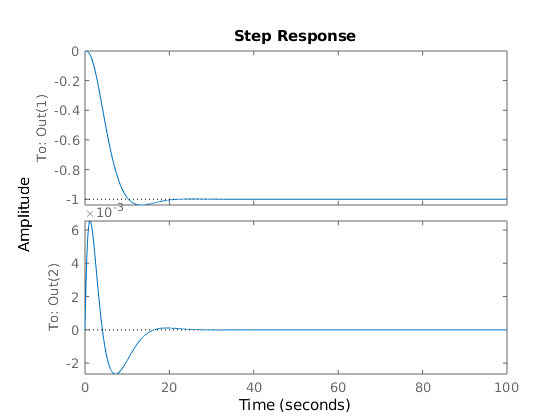

t = 0:0.01:100;
sys_cl = ss(A1-B1*K,B1,C1,D); % closed-loop system
step(sys_cl,t)

In order to observe the system's disturbance response, we must provide the proper input to the system. In this case, a disturbance is physically a mass on the cart. So the parameter m_cart is updated in the **B** matrix.  Modify the B matrix for closed-loop system to a have a **m_dist **term assuming that our current input is only the disturbance

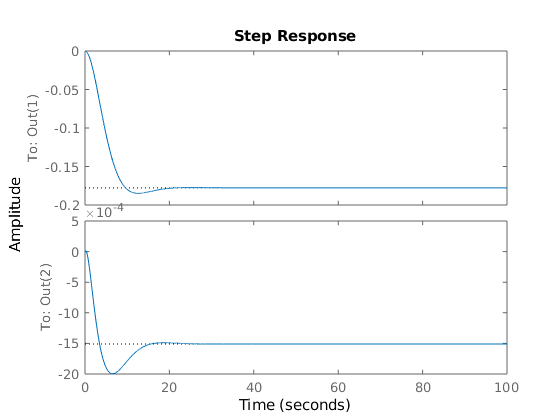

m_dist = 0.25; % mass of additional disturbance
B_dist = [0; 0; 0; m_dist];
dist_cl = ss(A1-B1*K,B_dist,C1,D); % closed-loop system
step(dist_cl,t)

Augmented State Space Model

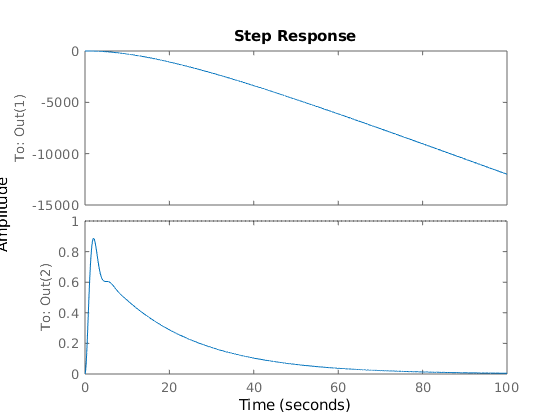

A_a = [A1 zeros(4,1); 0 0 1 0 0];
B_a = [B1;0];
B_r = [0;0;0;0;-1];
C_a = [C1 zeros(2,1)];
Ka = [K 150];
sysa_cl = ss(A_a-B_a*Ka,B_r,C_a,0);
step(sysa_cl,t)

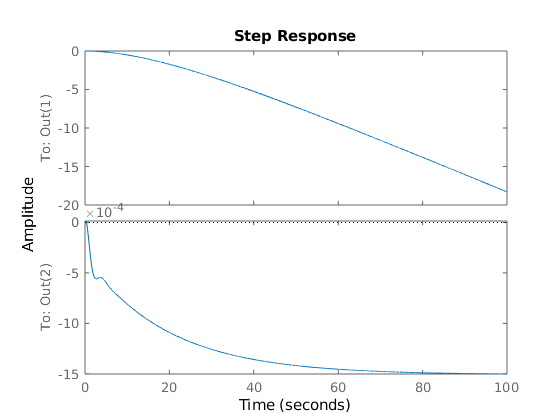

dist_cla = ss(A_a-B_a*Ka,[B_dist;0],C_a,D); % closed-loop system
step(dist_cla,t)

%Conversion to discrete model
a=tf(ss(A1-B1*K,B1,C1,D))


a =
 
  From input to output...
             1.105 s^2 + 4.083e-13 s - 183
   1:  -----------------------------------------
       s^4 + 1321 s^3 + 2030 s^2 + 881.4 s + 183
 
          18.66 s^2 - 3.141e-14 s + 4.15e-15
   2:  -----------------------------------------
       s^4 + 1321 s^3 + 2030 s^2 + 881.4 s + 183
 
Continuous-time transfer function.



b=c2d(a,0.2,'zoh');
c=minreal(ss(b));
%%
A=c.A;
B=c.B;
C=c.C;

%Finding required matrices for MPC
N = 10;  %This is the horizon for MPC
Qbar = [];
Rbar = [];
RbarD = [];
Sx = [];
CAB = [];

SU=[];
Su=[];
for ii = 1:N
    Qbar = blkdiag(Qbar,Q);
    Rbar = blkdiag(Rbar,R);
    RbarD = blkdiag(RbarD,RD);
    Sx = [Sx;C*A^ii];
    CAB = [CAB C*A^(ii-1)*B];
end
for ii = 1:N
    for jj = 1:ii  
        Su(ii,jj)=sum(CAB(1:ii-jj+1));
    end
    
end
Su;
Su1=  Su(:,1);
%%
LL = tril(ones(N));
H = 2*(LL'*Rbar*LL+RbarD+Su'*Qbar*Su);
Fu = 2*(diag(LL'*Rbar')'+Su1'*Qbar*Su)';  %Note the trick on Rbar - u(-1) is really a scalar
Fr = -2*(Qbar*Su)';
Fx = 2*(Sx'*Qbar*Su)';
%%
G =  [tril(ones(N));-tril(ones(N))];
W0 = 12*ones(2*N,1);
S =  zeros(2*N,4);
%%
%Initial state
X = [0;0;0;0];
T =  70;
%Considering xobj to be traveling in a straight line(r=xobj)
r= 5*ones(1,1000);%:0.01:50;
%r = square([1:T+N+1]/6);
Z = zeros(4,1);
U = 0;

options = optimoptions('quadprog');
options.Display = 'none';
Xact=[];
for ii = 1:T-1
    Xact(ii,:) = X;
    f = Fx*X+Fu*U+Fr*(r(ii:ii+N-1))';  %Subtracting offset value 5 from xobj
    W = W0+[ones(N,1)*-U;ones(N,1)*U];
    Z = quadprog(H,f,G,W+S*X,[],[],[],[],[],options); 
    Uopt(ii) = U + Z(1);     
    U = Uopt(ii);
    X = A*X+B*U;
end
Xact(ii+1,:) = X;
%%
y = C*Xact';

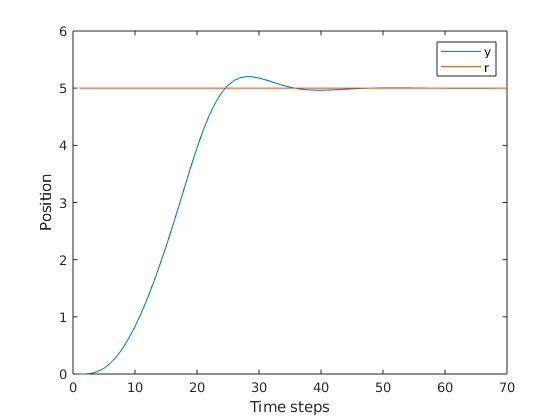

%Plots
figure
plot([1:T],y,[1:T],r(1:T))
xlabel('Time steps')
ylabel('Position')
legend('y','r')

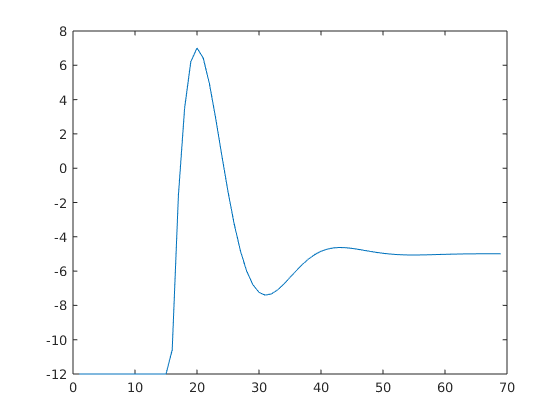

figure
plot(Uopt)